# Practico con utilitario 1

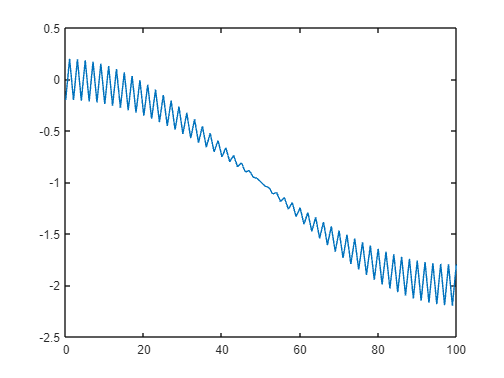

[n,senial_t] = senial(748695);
plot(n,senial_t);

La señal parece estar compuesta por dos señales armonicas, una de baja frecuencia con mayor amplitud y una de alta frecuencia y menor amplitud, ademas de un offset en continua de -1. Lo que esperaria ver en su transformada de Fourier son tres deltas, una en cero, por su componente continua, una en 1/200 por su componente de baja frecuencia y una en 1/2 por su componente de alta frecuencia

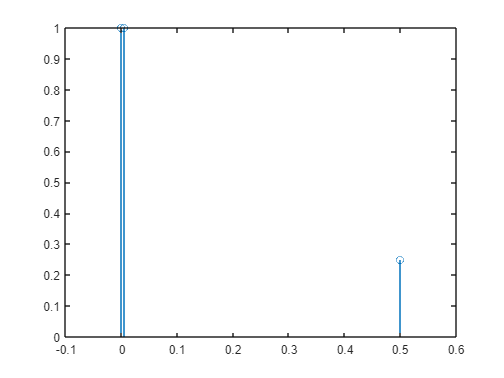

stem([0,0.005,0.5],[1,1,0.25]);
xlim([-0.1,0.6]);

Como solo tengo una cantidad finita de puntos de esta señal, la transformada que puedo calcular es la de la señal que va de menos infinito a infinito por un cajon de soporte 101, que es la cantidad de muestras con la que cuenta la señal muestreada. Debido a esto, la tranformada no van a ser tres deltas, sino que ceran tren sincs centradas en estas deltas

## Tranformada de Fourier de la señal de tiempo discreto (TFTD)

La TFTD de una señal de soporte finito; en este caso de k muestras, se puede calcular como:

    
$$X\left(s\right)=\sum_{n=0}^k x\left\lbrack n\right\rbrack \times e^{-\textrm{j2}\pi \textrm{sn}}$$


donde ***k*** es el numero de muestras de la señal y ***s ***es la frecuencia normalizada y es un numero real.

$X\left(s\right)$ es una funcion periodica de periodo 1, por lo que solo la voy a graficar entre $s=-\frac{1}{2}$ y $s=\frac{1}{2}$ , ya que mas alla de eso seria redundante. Tambien como s es un numero real, para calcular la** TFTD** numericamente voy a usar valores discretos de ***s*** con un paso $\textrm{ds}=0\ldotp 001$ 

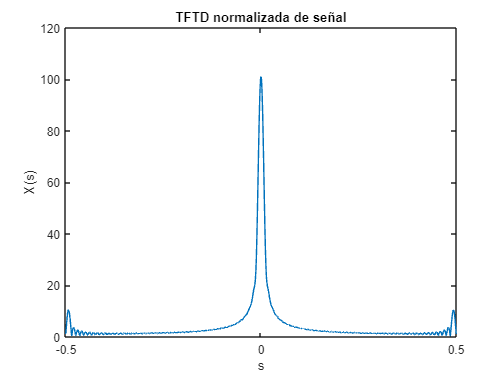

ds = 0.0001; s = -0.5:ds:0.5; senial_TFTD = zeros(1,length(s));

for i = 1:length(senial_TFTD)
    senial_TFTD(i) = sum(senial_t.*exp(-1j*2*pi*s(i)*n));
end

figure
plot(s,abs(senial_TFTD));
title('TFTD normalizada de señal')
xlabel('s')
ylabel('X(s)')

Tendria que ver tres picos, por que la señal tiene contenido en tres frecuencias, pero puedo ver solo dos porque no tengo suficiente resolucion de frecuencia como para dicernir entre la señal continua y la de baja frecuencia. Para poder dicernir entre ambas frecuencias necesitaria una mayor duracion de la señal, es decir un mayor numero de muestras.